% Example_5_2.mlx
%
% This is Example 5.2 from the paper 'Geometric modelling of 
% polycrystalline materials: Laguerre tessellations and periodic 
% semi-discrete optimal transport' by D.P. Bourne, M. Pearce & S.M. Roper.
%
% In this example we monitor the number of Newton iterations and 
% backtracking steps in 100 draws of 100,000 log-normally distributed 
% grain volumes.

clear

## Specify box dimensions

bx=[1,1,1];

## Specify periodicity

periodic=true;

## Specify maximum percentage error

percent_tol=1;

## Specify number of grains (seeds)

% Set n=[100000] to reproduce Example 5.2 from paper. 
% Note: n can be a vector to plot multiple figures, e.g., n=[1000,2000]
n=[1000]; 
nn=length(n);

## Specify number of experiments

nexp=100;

## Log-normal backtracking

% Parameters in log-normal distribution
ln_mean=1; % mean
std_dev=0.35; % standard deviation
sigma=sqrt((log(1+(std_dev/ln_mean)^2))); % log-normal parameter sigma
mu=-0.5*sigma^2+log(ln_mean); % log-normal parameter mu

disp('Log-normal')

Log-normal


for idx_n=1:nn
    % For each number of seeds

    fprintf('Calculating run times for n = %d\n',n(idx_n));
    
    % Initial guess is always w=0
    w_0=zeros(n(idx_n),1);
    
    for idx_exp=1:nexp
        % For each experiment

        fprintf('\t Experiment number %d',idx_exp);
        
        % Seed locations
        X=rand(n(idx_n),3);

        % Compute target volumes: 
        % Draw radii from log-normal distribution
        rad=lognrnd(mu,sigma,n(idx_n),1); 
        % Calculate the corresponding grain volumes 
        % (we don't need the factor 4pi/3 as we'll be renormalising)
        target_vols=rad.^3;
        % Normalise the volumes so that they add to the volume of the box
        target_vols=target_vols*prod(bx)/sum(target_vols); % target volumes of grains
        
        % Store X and target_vols in case later interrogation is required
        X_ln{idx_n,idx_exp}=X;
        tv_ln{idx_n,idx_exp}=target_vols;

        % Time the damped Newton method and return the number of Newton iterations and 
        % the number backtracking steps and error per Newton iteration 
        tic
        [w,max_percent_err,actual_vols,EXITFLAG,back_track_steps,newton_step_errors,w_steps] = ...
            SDOT_damped_Newton_diagnostic(w_0,X,target_vols,bx,periodic,percent_tol);
        t=toc;
        
        fprintf(' : completed in %f\n',t);
        
        % Store w in case later interrogation is required 
        w_ln{idx_n,idx_exp}=w;

        % Store the run time
        runtime_ln(idx_n,idx_exp)=t;

        % Store the deails of each Newton iteration 
        back_track_ln{idx_n,idx_exp}=back_track_steps; % number of backtracking steps
        newton_errors_ln{idx_n,idx_exp}=newton_step_errors; % volume errors
    end

    fprintf('Average run time %f\n',mean(runtime_ln(idx_n,:)'));
end

Calculating run times for n = 1000


	 Experiment number 1

 : completed in 1.506324


	 Experiment number 2

 : completed in 1.098448


	 Experiment number 3

 : completed in 1.079190


	 Experiment number 4

 : completed in 1.027656


	 Experiment number 5

 : completed in 1.428996


	 Experiment number 6

 : completed in 1.092184


	 Experiment number 7

 : completed in 1.327023


	 Experiment number 8

 : completed in 1.232720


	 Experiment number 9

 : completed in 1.346574


	 Experiment number 10

 : completed in 1.070452


	 Experiment number 11

 : completed in 1.069037


	 Experiment number 12

 : completed in 1.003413


	 Experiment number 13

 : completed in 1.388856


	 Experiment number 14

 : completed in 1.037560


	 Experiment number 15

 : completed in 1.058455


	 Experiment number 16

 : completed in 1.027993


	 Experiment number 17

 : completed in 1.394323


	 Experiment number 18

 : completed in 2.055955


	 Experiment number 19

 : completed in 1.030641


	 Experiment number 20

 : completed in 1.029591


	 Experiment number 21

 : completed in 1.081582


	 Experiment number 22

 : completed in 1.259757


	 Experiment number 23

 : completed in 1.531471


	 Experiment number 24

 : completed in 1.204591


	 Experiment number 25

 : completed in 1.151943


	 Experiment number 26

 : completed in 1.131449


	 Experiment number 27

 : completed in 1.209645


	 Experiment number 28

 : completed in 1.324846


	 Experiment number 29

 : completed in 1.118455


	 Experiment number 30

 : completed in 1.177718


	 Experiment number 31

 : completed in 1.392923


	 Experiment number 32

 : completed in 1.428867


	 Experiment number 33

 : completed in 1.168189


	 Experiment number 34

 : completed in 1.501307


	 Experiment number 35

 : completed in 1.155867


	 Experiment number 36

 : completed in 1.138861


	 Experiment number 37

 : completed in 1.436306


	 Experiment number 38

 : completed in 1.155986


	 Experiment number 39

 : completed in 1.405713


	 Experiment number 40

 : completed in 1.337510


	 Experiment number 41

 : completed in 1.411493


	 Experiment number 42

 : completed in 1.581229


	 Experiment number 43

 : completed in 1.259929


	 Experiment number 44

 : completed in 1.148545


	 Experiment number 45

 : completed in 1.469686


	 Experiment number 46

 : completed in 1.155850


	 Experiment number 47

 : completed in 1.225591


	 Experiment number 48

 : completed in 1.394405


	 Experiment number 49

 : completed in 1.431370


	 Experiment number 50

 : completed in 1.372443


	 Experiment number 51

 : completed in 0.968645


	 Experiment number 52

 : completed in 1.174717


	 Experiment number 53

 : completed in 1.378907


	 Experiment number 54

 : completed in 1.210051


	 Experiment number 55

 : completed in 1.581974


	 Experiment number 56

 : completed in 0.922892


	 Experiment number 57

 : completed in 1.178026


	 Experiment number 58

 : completed in 1.183399


	 Experiment number 59

 : completed in 1.264156


	 Experiment number 60

 : completed in 1.184705


	 Experiment number 61

 : completed in 1.455063


	 Experiment number 62

 : completed in 1.244255


	 Experiment number 63

 : completed in 1.226493


	 Experiment number 64

 : completed in 1.129947


	 Experiment number 65

 : completed in 1.445736


	 Experiment number 66

 : completed in 1.300462


	 Experiment number 67

 : completed in 1.362114


	 Experiment number 68

 : completed in 1.406853


	 Experiment number 69

 : completed in 1.370961


	 Experiment number 70

 : completed in 1.692761


	 Experiment number 71

 : completed in 1.220502


	 Experiment number 72

 : completed in 1.425904


	 Experiment number 73

 : completed in 1.297158


	 Experiment number 74

 : completed in 1.135142


	 Experiment number 75

 : completed in 1.482277


	 Experiment number 76

 : completed in 1.287909


	 Experiment number 77

 : completed in 1.356102


	 Experiment number 78

 : completed in 1.191716


	 Experiment number 79

 : completed in 1.377356


	 Experiment number 80

 : completed in 1.226474


	 Experiment number 81

 : completed in 1.439361


	 Experiment number 82

 : completed in 1.221062


	 Experiment number 83

 : completed in 1.155236


	 Experiment number 84

 : completed in 1.572126


	 Experiment number 85

 : completed in 1.140746


	 Experiment number 86

 : completed in 1.122008


	 Experiment number 87

 : completed in 1.176358


	 Experiment number 88

 : completed in 1.160812


	 Experiment number 89

 : completed in 1.101424


	 Experiment number 90

 : completed in 1.180704


	 Experiment number 91

 : completed in 1.353230


	 Experiment number 92

 : completed in 1.236757


	 Experiment number 93

 : completed in 1.502687


	 Experiment number 94

 : completed in 1.395969


	 Experiment number 95

 : completed in 1.240991


	 Experiment number 96

 : completed in 1.445291


	 Experiment number 97

 : completed in 1.451920


	 Experiment number 98

 : completed in 1.469439


	 Experiment number 99

 : completed in 1.460813


	 Experiment number 100

 : completed in 1.164625


Average run time 1.277431


## Plot the results

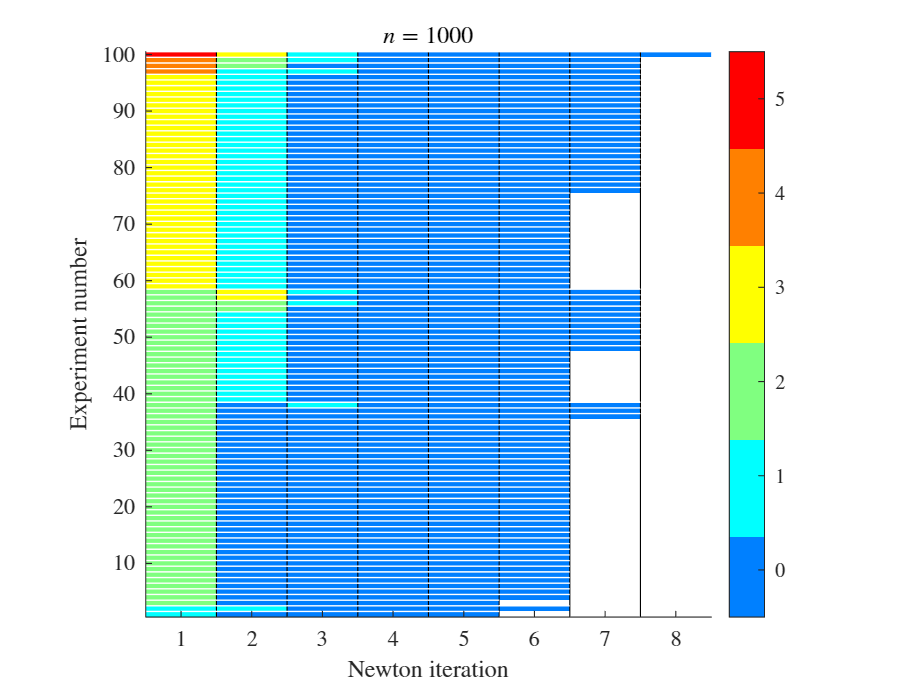

% Generate Figure 2 from the paper

for k=1:nn

    back_track_exp=back_track_ln(k,:);

    % First find maximum number of Newton steps
    newt_steps=cellfun('length',back_track_exp);
    mns=max(newt_steps);
    data=-1*ones(nexp,mns);

    % Extract the data from the backtracking cell array
    for j=1:nexp
        data(j,1:length(back_track_exp{j}))=back_track_exp{j};
    end

    % Sort the data for ease of visualisation
    data=sortrows(data);

    % The maximum number of backtracking steps
    mbs=max(max(data));

    % Make a new figure, one for each number of cells
    figure(k)
    
    % Plot the number of backtracking steps
    image(1:mns,1:nexp,data,'CDataMapping','scaled')
    title(sprintf('$n=%d$',n(k)),'Interpreter','latex','Fontsize',12)

    % Make a discrete colour palette
    cmap=jet(mbs+2);
    % Make -1 correspond to white
    cmap(1,:)=[1 1 1];

    colormap(cmap);
    cbh=colorbar;
    ch=(mbs)/(mbs+1);
    cbh.Ticks=linspace(0.5*ch, mbs-0.5*ch, mbs+1) ; %Create 8 ticks from zero to 1
    cbh.TickLabels=num2cell(0:mbs);
    cbh.Limits=[0,mbs];
    xlabel('Newton iteration','Interpreter','latex','Fontsize',12)
    ylabel('Experiment number','Interpreter','latex','Fontsize',12)
    xlim([0.5,mns+0.5]);
    ylim([0.5,nexp+0.5]);

    set(gca,'YDir','normal','TickLabelInterpreter','latex','Fontsize',10,'box','off');
    set(gca,'XTickLabelMode','manual');
    set(gca,'XTickLabels',num2cell(1:mns));
    set(gca,'XTickMode','manual');
    set(gca,'XTick',1:mns);
    
    hold on
    for l=1:mns-1
        plot(0.5+[l l],[0.5,nexp+0.5],'k');
    end

    for l=1:nexp
        % Number of Newton steps
        ns=sum(data(l,:)>=0);
        plot([0 ns+0.5],0.5+[1 1]*l,'w','LineWidth',0.25);
    end
    hold off

    set(cbh,'TickLabelInterpreter','latex');
    axis square
    
end